train_data_csv = datastore('C:\Users\ZIN\Documents\GitHub\predict_blood_glucose\scv\train*.csv');
test_data_csv = datastore('C:\Users\ZIN\Documents\GitHub\predict_blood_glucose\scv\test*.csv');

Rdata = read(train_data_csv);
Tdata = read(test_data_csv);

% 데이터 불러 오기 

Rdata = table2array(Rdata)';
Tdata =  table2array(Tdata)';
d = 0.2;
% num=numel(data);
count = 0;
for num = 1:numel(Rdata(1,:))
    if(Rdata(2,num)>0)
        count = Rdata(2,num);
    end
    Rdata(2,num) = count;
    count = count-d;
    if(count <= 0)
        count = 0;
    end
    count;
end
for num = 1:numel(Tdata(1,:))
    if(Tdata(2,num)>0)
        count = Tdata(2,num);
    end
    Tdata(2,num) = count;
    count = count-d;
    if(count <= 0)
        count = 0;
    end
    count;
end
[layers,options] = InitialOption();
[net,mu,sig,YTrainend]=trainning(Rdata,layers,options);

[YPred] = Predict2(net,Standard(Tdata,mu,sig));
YPred = Destandard(YPred, mu, sig);
Rmse(YPred,Tdata(1,:));

rmse = 1.3712

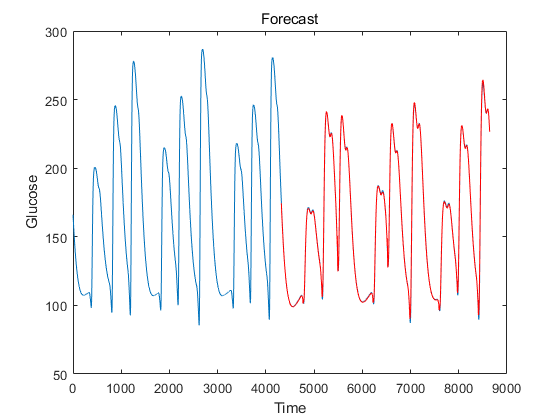

Dataplot(Rdata(1,:),Tdata(1,:),YPred)

function [YPred] = Predict1(net,n,YTrain)
    
    YPred = zeros(1,n);
    [net,YPred] = predictAndUpdateState(net,YTrain);
    for Num = 2:n   
         [net,YPred(Num)] = predictAndUpdateState(net,YPred(Num-1)); 
    end    
end
function [YPred] = Predict2(net,Tdata)
    n = numel(Tdata(1,:));
    YPred = zeros(1,n);
    for Num = 1:n   
         [net,YPred(Num)] = predictAndUpdateState(net,[Tdata(1,Num);Tdata(2,Num)] ); 
    end    
end

function [StandardizedData, mu, sig] = Standard(data,mu,sig)
    if (mu == 0)
        mu = mean(data');
    end  
    if (sig ==0)
        sig = std(data');
    end
    %표준화를 위해 학습용 데이터들에 대한 평균과 표쥰편차 할당
    
    StandardizedData = [(data(1,:) - mu(1,1))/ sig(1,1); (data(2,:) - mu(1,2))/ sig(1,2)];
    %데이터의 평균과 표준편차를 통해 표준화 수행
end


function DestandardizedData = Destandard(data, mu, sig)
    DestandardizedData = sig(1,1)*data + mu(1,1);
    %표준화 해제
end

function rmse = Rmse(YPred,Tdata)
    rmse = sqrt(mean((YPred-Tdata).^2))
end

function [net,mu,sig,YTrainend] = trainning(data,layers,options)  
    
    numTimeStepsTrain = floor(numel(data(1,:)));
    dataTrain = data(:,1:numTimeStepsTrain);
    [dataTrainStandardized, mu, sig] = Standard(dataTrain,0,0);
     XTrain = [dataTrainStandardized(1,1:end-1);dataTrainStandardized(2,1:end-1)];
     YTrain = [dataTrainStandardized(1,2:end)];
%          XTrain = [dataTrainStandardized(1:end-1,1) dataTrainStandardized(1:end-1,2)]
%          YTrain = [dataTrainStandardized(2:end,1) dataTrainStandardized(2:end,2)]
     net = trainNetwork(XTrain,YTrain,layers,options);
     net = predictAndUpdateState(net,XTrain);
     YTrainend = YTrain(end);
end

function Dataplot(data,Tdata,YPred)
    ntrain = numel(data);
    ntest = numel(Tdata);          
    idx = ntrain+1:(ntrain+ntest);
    figure
    plot([data(1,:) Tdata])
    %학습데이터를 그래프로 표시
    hold on
    %새로운 그래프를 추가하고 기존 그래프에 통합
    plot(idx,YPred,'r-')
    %예측된 데이터를 그래프로 표현
    hold off
    xlabel("Time")
    ylabel("Glucose")
    title("Forecast")
%     if(max(YPred)>max(data))
%         M = max(YPred);
%     else
%         M = max(data);
%     end
%     
%     if(min(YPred)>min(data))
%         m = min(data);
%     else
%         m = min(YPred);
%     end
%     
%     ntrain = ntrain+ntest;
%      xlim([0,ntrain+10]) %      xlim([ntrain-ntest-10,ntrain+10])
%       ylim([m-30,M+30])
%     legend(["Observed" "Forecast"])
%     
%     figure
%     plot(data')
%     xlabel("Time")
%     ylabel("Glucose")
%     title("환자의 혈당") 
%     xlim([ntrain-ntest-10,ntrain+10]) 
%     ylim([m-30,M+30])
end

function [layers,options] = InitialOption()
numFeatures = 2;
numResponses = 1;
numHiddenUnits = 15;
%은닉계층을 150개로 설정

layers = [
    sequenceInputLayer(numFeatures)
    lstmLayer(numHiddenUnits)
    fullyConnectedLayer(numResponses)
    regressionLayer];
    %입력 및 응답레이어를 각각 1개로 설정하고 200개의 은닉계층을 갖는 선형 레이어 구성

options = trainingOptions('adam',... %adam경사하강법 채택
    'MaxEpochs', 250, ... % 250회 반복
    'GradientThreshold', 2, ... %기울기 임계값 설정
    'InitialLearnRate', 0.005, ...  %초기 학습률
    'LearnRateSchedule', 'piecewise', ... 
    'LearnRateDropPeriod', 125,... %125회마다 학습률 변화
    'LearnRateDropFactor', 0.2, ...%0.2만큼 학습률 감소
    'Verbose', 0);%,'plots','training-progress'); %학습과정에 대한 그래프 표시
end





